**Tokyo's mortality data**

The purpose of this file is to showcase the mortality data for Tokyo. Tokyo is the 41st prefecture in this dataset.

**Import data**

load Data\mortality_rates_array.mat
load  Data\mortality_rates.mat

age = 0:95;
year = 1:45;
nyears = 45;
tokyo = squeeze(mortality_rates_array(:,41,:)); % format is {age,prefecture,year}

 **Preliminary Visualizations**

The raw data and corresponding log transformation show that mortality clearly decreases with year. Black lines are older, while 

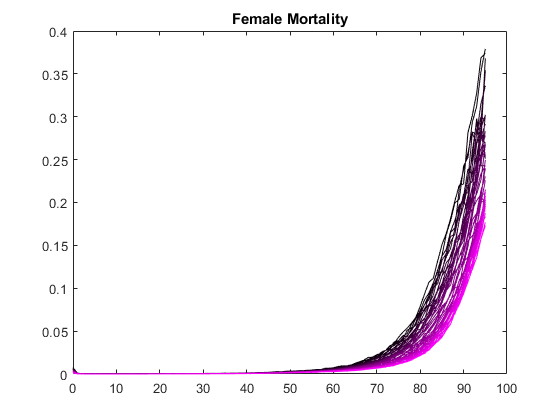


for j = 1:nyears
    plot(age,tokyo(:,j),'color',[year(j)/max(year),0,year(j)/max(year)])
    hold on
end
title("Female Mortality")
hold off

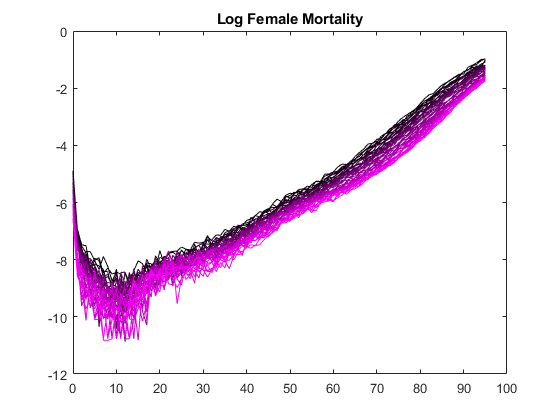



for j = 1:nyears
    plot(age,log(tokyo(:,j)),'color',[year(j)/max(year),0,year(j)/max(year)])
    hold on
end
title("Log Female Mortality")
hold off

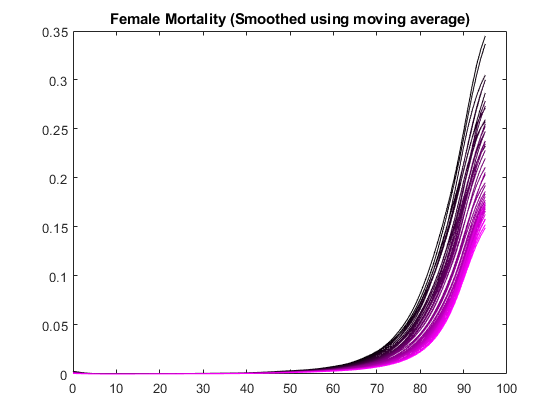


smoothtokyo = smoothdata(tokyo,'gaussian');

for j = 1:nyears
    plot(age,smoothtokyo(:,j),'color',[year(j)/max(year),0,year(j)/max(year)])
    hold on
end
title("Female Mortality (Smoothed using moving average)")
hold off

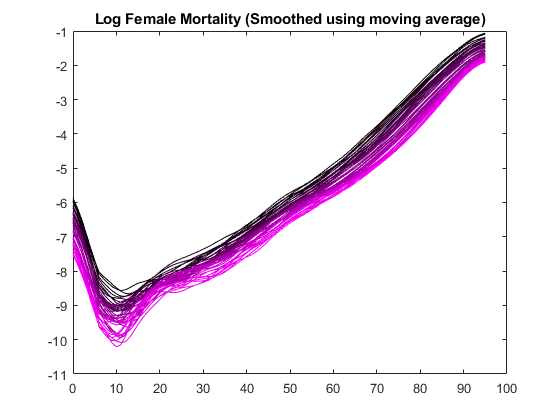


for j = 1:nyears
    plot(age,log(smoothtokyo(:,j)),'color',[year(j)/max(year),0,year(j)/max(year)])
    hold on
end
title("Log Female Mortality (Smoothed using moving average)")
hold off